%hello
clear;
T = readtable('sa-person-2019.csv');

% T_tb = To(strcmp(To.HLT_CHRONIC_TB, 'Yes'),:)
T_hiv = T(strcmp(T.HLT_CHRONIC_HIV, 'Yes'),:)

T_hiv = 2138×149 table
      uqnr       personnr       psu             prov          Four_by_Four       Sex        age       age_grp1           Population                             HHC_RELATIONSHIP                                                            HHC_MARITAL                                              SPOUSE             SPOUSE_NAME        HHC_FATH_ALIVE     HHC_FATH_PARTHH        HHC_FATH_NAME       HHC_MOTH_ALIVE     HHC_MOTH_PARTHH        HHC_MOTH_NAME                                                             Education                                                              ECD_CHLDATT            ECD_NOTAT

T = T_hiv

T = 2138×149 table
      uqnr       personnr       psu             prov          Four_by_Four       Sex        age       age_grp1           Population                             HHC_RELATIONSHIP                                                            HHC_MARITAL                                              SPOUSE             SPOUSE_NAME        HHC_FATH_ALIVE     HHC_FATH_PARTHH        HHC_FATH_NAME       HHC_MOTH_ALIVE     HHC_MOTH_PARTHH        HHC_MOTH_NAME                                                             Education                                                              ECD_CHLDATT            ECD_NOTATT


% Split classes
minority = T(strcmp(T.HLT_CHRONIC_TB, 'Yes'),:);
majority = T(strcmp(T.HLT_CHRONIC_TB, 'No'),:);
rng=2

rng = 2


% Randomly downsample majority
idx = randperm(height(majority), floor(1.4*height(minority)));
majority_down = majority(idx, :);

% Combine balanced table
T = [minority; majority_down];

responseVar = 'HLT_CHRONIC_TB';
excludeVars = {responseVar};
% GENHEALTH and ILLNESS_SCBLOOD are symptoms of TB
% LAB_SALARY and LAB_STO have most entries not reported
% EDU_RSNN includes illness and is very specific for education (reason for
% non-attendance, presumably at educational institution)
excludeVars = {responseVar, 'HLT_GENHEALTH', 'HLT_ILLNESS_SCBLOOD', 'LAB_SALARY', 'LAB_STO', 'EDU_RSNN',...
    'HLT_CONSULT', 'LAB_GOVPROG'}; % TB = bad health, these are correlated
% Use all other columns as predictors
predictorVars = setdiff(T.Properties.VariableNames, excludeVars);

% hltVarLocs = contains(predictorVars, 'HLT');
% predictorVars = predictorVars(hltVarLocs);

% Calculate class weights manually (inverse frequency)
classNames = categories(categorical(T.HLT_CHRONIC_TB))

classNames = 2×1 cell array
    {'No' }
    {'Yes'}


counts = [sum(strcmp(T.HLT_CHRONIC_TB, 'No')), sum(strcmp(T.HLT_CHRONIC_TB, 'Yes'))] 

counts =    124    89


total = sum(counts)

total = 213

weights = total ./ (length(counts) * counts)  % Inverse of frequency

weights =     0.8589    1.1966



% Create a cost matrix (optional alternative)
costMatrix = [0 weights(2); weights(1) 0];  % Cost of misclassifying each class
% Fit decision tree classifier
model = fitctree(T, responseVar, ...
    'PredictorNames', predictorVars, ...
    'ResponseName', responseVar, 'MinLeafSize',10, ...
    'ClassNames', classNames, 'cost', costMatrix);%, 'CrossVal','on');

% Fit decision tree classifier
% treeModel = fitctree(T, responseVar, ...
%     'PredictorNames', predictorVars, ...
%     'ResponseName', responseVar, 'MaxNumSplits',15);%, 'CrossVal','on');

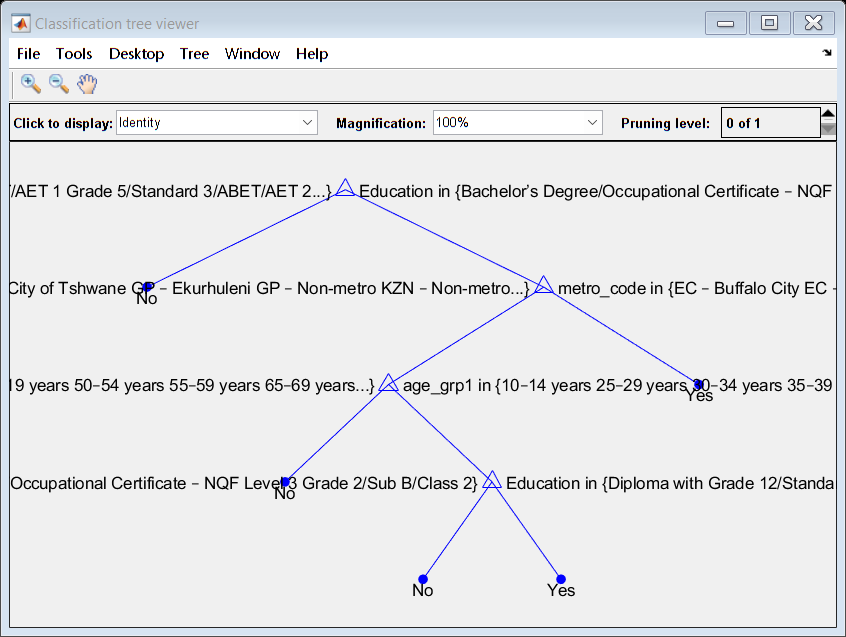

% classError = kfoldLoss(treeModel)
% model = treeModel.Trained{1};

view(model, 'Mode', 'graph');

% Predict on the training set
predictedLabels = predict(model, T_hiv);

% Compare with actual labels
cm = confusionmat(T_hiv.HLT_CHRONIC_TB, predictedLabels)

cm =         1554         495
          30          59


tp = cm(1,1)

tp = 1554

fn = cm(1,2)

fn = 495

fp = cm(2,1)

fp = 30

tn = cm(2,2)

tn = 59


accuracy = (tp+tn)/(tp+tn+fp+fn)

accuracy = 0.7544

precision = tp/(tp+fp)

precision = 0.9811

recall = tp/(tp+fn)

recall = 0.7584

f1 = 2*precision*recall/(precision+recall)

f1 = 0.8555

specificity = tn/(tn+fp)

specificity = 0.6629

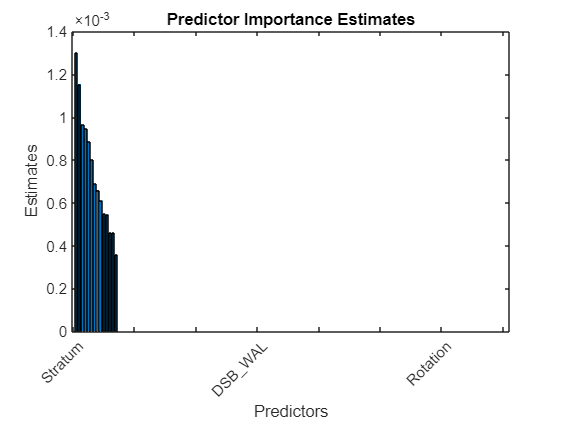

% Compute importance of each predictor
importance = predictorImportance(model);
takeFirst = 10;

% Plot feature importance
figure;
% Sort values descending
[sortedValues, sortIdx] = sort(importance, 'descend');
sortedLabels = predictorVars(sortIdx(1:takeFirst));

figure(1);
bar(sortedValues);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = sortedLabels;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';